imds = imageDatastore('/Users/Harsh/Documents/GSU_Spring/ComputerVision/Harsh_Assignment_3/Q6/images',['IncludeS' ...
    'ubfolders'],true,'LabelSource','foldernames');

tbl = countEachLabel(imds)

tbl = 5×2 table
    Label     Count
    ______    _____

    fork       10  
    glass      10  
    kettle     10  
    knife      10  
    spoon      10  


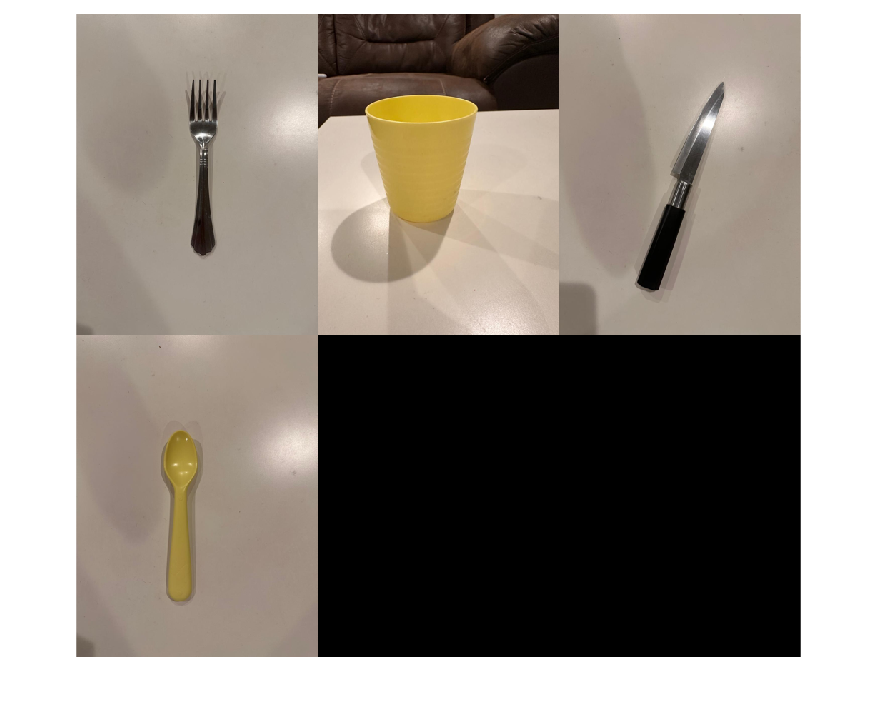

figure
montage(imds.Files(1:16:end))

% prepare data
[trainingSet, validationSet] = splitEachLabel(imds, 0.6, 'randomize');

bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: fork
* Image category 2: glass
* Image category 3: kettle
* Image category 4: knife
* Image category 5: spoon
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 30 images...done. Extracted 2304000 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 1843200
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 47/100 iterations (~18.30 seconds/iteration)...converged in 47 iterations.

* Finished creating Bag-Of-Features



img = readimage(imds, 1);
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


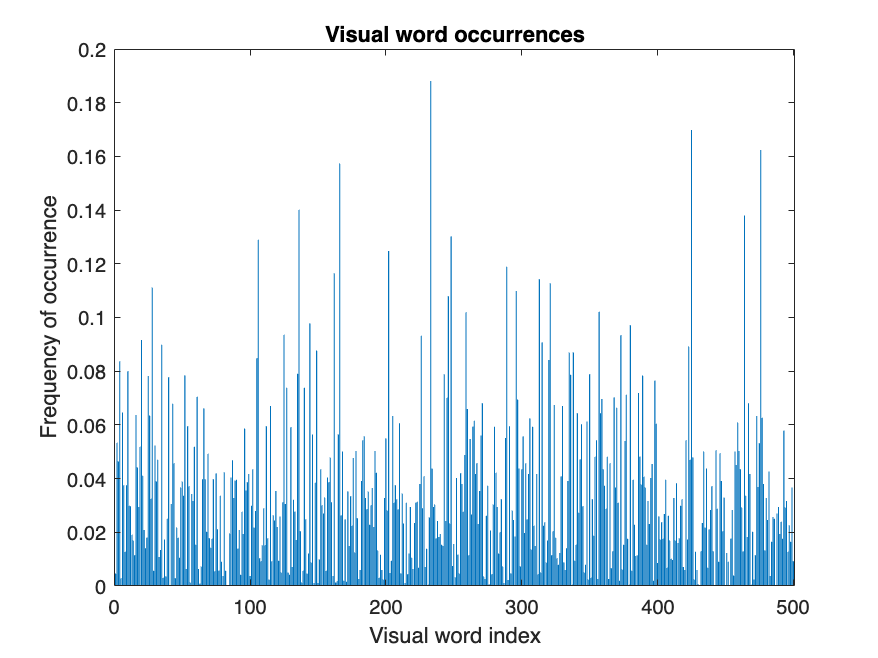

% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

% categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);
categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Training an image category classifier for 5 categories.
--------------------------------------------------------
* Category 1: fork
* Category 2: glass
* Category 3: kettle
* Category 4: knife
* Category 5: spoon

* Encoding features for 30 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



confMatrix = evaluate(categoryClassifier, trainingSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: fork
* Category 2: glass
* Category 3: kettle
* Category 4: knife
* Category 5: spoon

* Evaluating 30 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                           PREDICTED
KNOWN     | fork   glass   kettle   knife   spoon   
----------------------------------------------------
fork      | 1.00   0.00    0.00     0.00    0.00    
glass     | 0.00   1.00    0.00     0.00    0.00    
kettle    | 0.00   0.00    1.00     0.00    0.00    
knife     | 0.00   0.00    0.00     1.00    0.00    
spoon     | 0.33   0.00    0.00     0.00    0.67    

* Average Accuracy is 0.93.



confMatrix = evaluate(categoryClassifier, validationSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: fork
* Category 2: glass
* Category 3: kettle
* Category 4: knife
* Category 5: spoon

* Evaluating 20 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                           PREDICTED
KNOWN     | fork   glass   kettle   knife   spoon   
----------------------------------------------------
fork      | 1.00   0.00    0.00     0.00    0.00    
glass     | 0.00   1.00    0.00     0.00    0.00    
kettle    | 0.00   0.00    1.00     0.00    0.00    
knife     | 0.00   0.00    0.00     1.00    0.00    
spoon     | 0.50   0.00    0.00     0.00    0.50    

* Average Accuracy is 0.90.



% Compute average accuracy
mean(diag(confMatrix))

ans = 0.9000

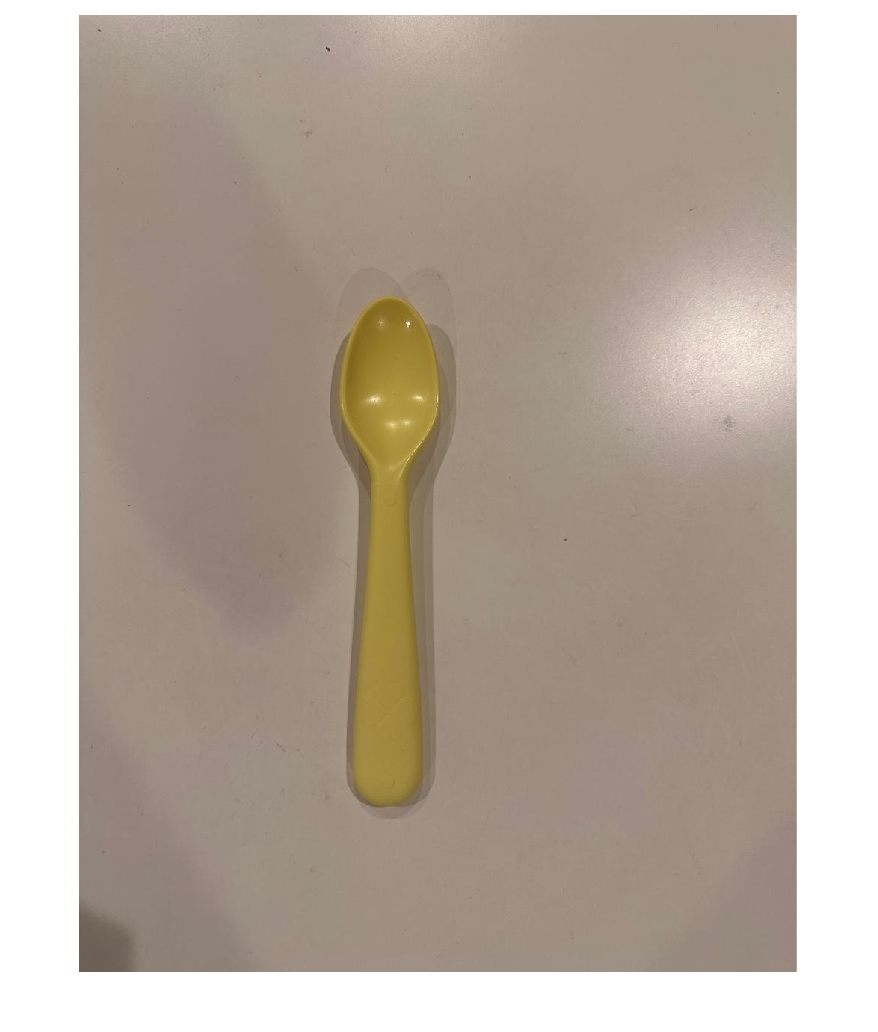

img = imread(fullfile('/Users/Harsh/Documents/GSU_Spring/ComputerVision/Harsh_Assignment_3/Q6/images/','spoon','8.jpeg'));
figure
imshow(img)

[labelIdx, scores] = predict(categoryClassifier, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1×1 cell array
    {'spoon'}
